clear; clc; close all;

% Part 1
fprintf('-------------------- Part 1 : Import and clean the data --------------------\n');

-------------------- Part 1 : Import and clean the data --------------------


% Load and clean data from the last 3 years 
fprintf('...Loading and cleaning weather data...\n');

...Loading and cleaning weather data...


[cleaned_data_2024, cleaned_data_2023, cleaned_data_2022] = function_clean_data();

% Importing station coordinates
fprintf('...Importing station coordinates...\n');

...Importing station coordinates...



filename = 'coordonnees_stations.csv';
opts = detectImportOptions(filename, 'Delimiter',';', 'VariableNamingRule','preserve');
T = readtable(filename, opts);

% Part 2
fprintf('-------------------- Part 2 : Map of stations --------------------\n');

-------------------- Part 2 : Map of stations --------------------


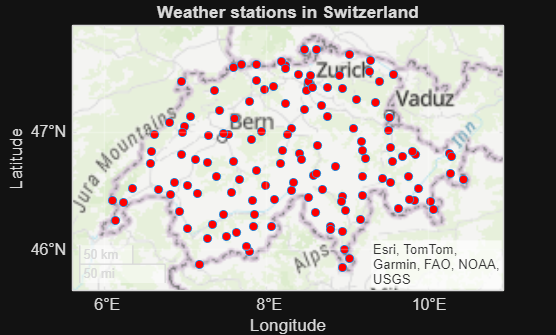


% Extract the relevant columns
altitude = T.('Hauteur de mesure m s. mer');
lat = T.Latitude;
lon = T.Longitude;
abreviation = string(T.('Abr.'));   % Garder l'abréviation

% Create the figure and the map centered on Switzerland
figure
gx = geoaxes; 
geobasemap(gx,'topographic'); 
hold on

% Add the points
p = geoplot(gx, lat, lon, 'o', 'MarkerFaceColor','r', 'MarkerSize',5);
title('Weather stations in Switzerland')

% Define all the info tips directly - REMPLACER Station par Abréviation
p.DataTipTemplate.DataTipRows = [ ...
    dataTipTextRow('Abréviation', abreviation), ...
    dataTipTextRow('Altitude (m)', altitude), ...
    dataTipTextRow('Latitude', lat), ...
    dataTipTextRow('Longitude', lon)];

% Center the map
geolimits(gx, [min(lat)-0.2 max(lat)+0.2], [min(lon)-0.2 max(lon)+0.2])

% Part 3
fprintf('-------------------- Part 3 : Sunshine analysis --------------------\n');

-------------------- Part 3 : Sunshine analysis --------------------



 Analysis for 2024 : 



The sunniest station : OTL (10313 min)


Least sunny station : ELM (5174 min)


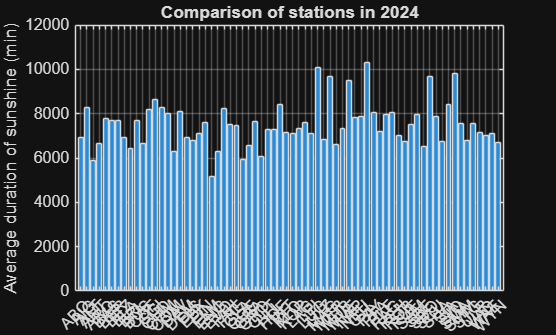


 Analysis for 2023 : 



The sunniest station : OTL (11726 min)


Least sunny station : ELM (6050 min)


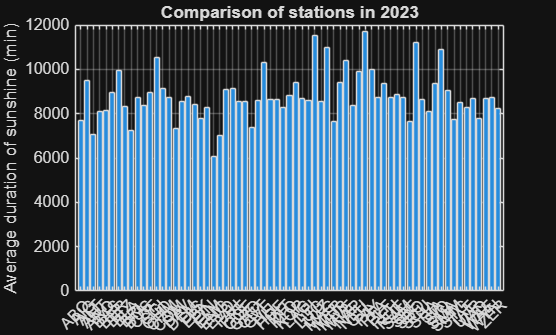


 Analysis for 2022 : 



The sunniest station : OTL (12887 min)


Least sunny station : ELM (6815 min)


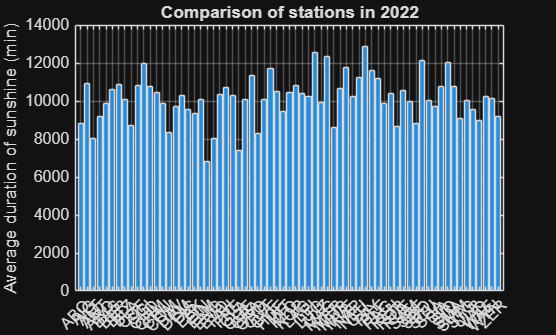

% ANALYSE_ENSOLEILLEMENT_AL

annees = [2024, 2023, 2022];
cleaned_sets = {cleaned_data_2024, cleaned_data_2023, cleaned_data_2022};
all_years_data = struct([]);

for a = 1:numel(annees)
    target_year = annees(a);
    cleaned_data = cleaned_sets{a};

    % Supprimer les entrées vides
    nonEmptyIdx = ~cellfun(@isempty, cleaned_data);
    cleaned_data = cleaned_data(nonEmptyIdx);

    fprintf('\n Analysis for %d : \n', target_year);

    %% ---- Moyenne sur toutes les stations ----
    all_data = vertcat(cleaned_data{:});

    dates = all_data.Date;
    sunshine_min = all_data.sre000m0;
    sunshine_percent = all_data.sremaxmv;

    year_month = datetime(year(dates), month(dates), 1);
    [unique_months, ~, month_idx] = unique(year_month);

    monthly_min = accumarray(month_idx, sunshine_min, [], @mean);
    monthly_percent = accumarray(month_idx, sunshine_percent, [], @mean);

    monthly_avg = table(unique_months, monthly_min, monthly_percent, ...
        'VariableNames', {'Date', 'mean_sre000m0', 'mean_sremaxmv'});
    monthly_avg = sortrows(monthly_avg, 'Date');

    %% ---- Comparaison globale ----
    station_names = all_data{:,1};
    sre000m0_values = all_data.sre000m0;
    tbl = table(station_names, sre000m0_values);
    station_avg = varfun(@mean, tbl, 'InputVariables','sre000m0_values', ...
        'GroupingVariables','station_names');

    [~, idxMax] = max(station_avg.mean_sre000m0_values);
    [~, idxMin] = min(station_avg.mean_sre000m0_values);

    fprintf('\nThe sunniest station : %s (%.0f min)\n', ...
        char(station_avg.station_names(idxMax)), station_avg.mean_sre000m0_values(idxMax));
    fprintf('Least sunny station : %s (%.0f min)\n', ...
        char(station_avg.station_names(idxMin)), station_avg.mean_sre000m0_values(idxMin));

    % Graphs 
    figure('Name', ['Station comparison' num2str(target_year)], 'NumberTitle', 'off');
    bar(categorical(station_avg.station_names), station_avg.mean_sre000m0_values);
    xtickangle(45);
    ylabel('Average duration of sunshine (min)');
    title(['Comparison of stations in ' num2str(target_year)]);
    grid on;
end

% Part 4
fprintf('-------------------- Part 4 : Calculation of cell temperature --------------------\n');

-------------------- Part 4 : Calculation of EPOA and cell temperature --------------------



% Calculation of the EPOA for each year 
EPOA_2024 = function_EPOA(cleaned_data_2024, T) ;
EPOA_2023 = function_EPOA(cleaned_data_2023, T);
EPOA_2022 = function_EPOA(cleaned_data_2022, T);

%% Calculation of PV cell temperature for each year
Tcell_2024 = function_Tcell(EPOA_2024, cleaned_data_2024);
Tcell_2023 = function_Tcell(EPOA_2023, cleaned_data_2023);
Tcell_2022 = function_Tcell(EPOA_2022, cleaned_data_2022);

% End
fprintf('\n Calculations of EPOA cell temperature completed for 2024, 2023 and 2022 \n');


 Calculations of EPOA and cell temperature completed for 2024, 2023 and 2022 


% Part 5
fprintf('-------------------- Part 5 : Calculation of the efficiency of a photovoltaic panel based on cell temperature --------------------\n');

-------------------- Part 5 : Calculation of the efficiency of a photovoltaic panel based on cell temperature --------------------



mex pv_efficiency.c

Building with 'Microsoft Visual C++ 2022 (C)'.
MEX completed successfully.


[eta, P, Tcell, station] = pv_efficiency();  % appel du code C

Automatic PV simulation with CSV export
Technology: Monocrystalline silicon (PERC, TOPCon)
eta_ref = 21.00%, Tref = 25.0°C, beta = 0.0045 1/°C, G = 1000 W/m², A = 1.0 m²


Results saved in 'results.csv'
